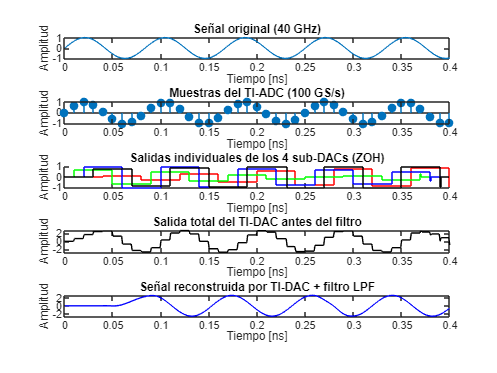

clc; clear; close all;

%% Parámetros generales
Fs_signal = 1000e9;          % Resolución de simulación: 200 GS/s
f = 12e9;                   % Frecuencia de la señal original: 40 GHz
t_total = 0.4e-9;           % Duración total: 0.4 ns
t = 0:1/Fs_signal:t_total;  % Tiempo continuo para señal analógica

%% Señal original
x = sin(2*pi*f*t);          % Señal senoidal original (entrada al TI-ADC)

%% Parámetros TI-ADC
M = 4;
Fs_adc = 25e9;
Fs_total = M * Fs_adc;
Ts_total = 1 / Fs_total;
t_adc = 0:Ts_total:t_total;

% Simular muestreo con TI-ADC
x_ti_adc = zeros(1, length(t_adc));
t_sub = cell(1, M);
x_sub = cell(1, M);

for m = 1:M
    t_m = t_adc(m:M:end);
    x_m = sin(2*pi*f*t_m);
    t_sub{m} = t_m;
    x_sub{m} = x_m;
    x_ti_adc(m:M:end) = x_m;
end

%% TI-DAC con ZOH
x_out_sub = zeros(M, length(t));
for m = 1:M
    x_out_sub(m, :) = interp1(t_sub{m}, x_sub{m}, t, 'previous', 0);
end

x_out_dac = sum(x_out_sub, 1);  % Señal compuesta de los 4 DACs

%% Filtro pasa bajos (reconstrucción)
fc = 60e9;                           % Frecuencia de corte: 60 GHz
norm_fc = fc / (Fs_signal/2);       % Frecuencia normalizada

% Diseño de filtro FIR
lpf = designfilt('lowpassfir', 'FilterOrder', 100, ...
                 'CutoffFrequency', norm_fc, 'DesignMethod', 'window');

x_out_filtered = filter(lpf, x_out_dac);   % Salida filtrada

%% Gráficas
figure;

subplot(5,1,1);
plot(t*1e9, x);
title('Señal original (40 GHz)');
xlabel('Tiempo [ns]'); ylabel('Amplitud');
xlim([0 t_total*1e9]);

subplot(5,1,2);
stem(t_adc*1e9, x_ti_adc, 'filled');
title('Muestras del TI-ADC (100 GS/s)');
xlabel('Tiempo [ns]'); ylabel('Amplitud');
xlim([0 t_total*1e9]);

subplot(5,1,3);
hold on;
colors = {'r','g','b','k'};
for m = 1:M
    stairs(t*1e9, x_out_sub(m,:), 'Color', colors{m});
end
title('Salidas individuales de los 4 sub-DACs (ZOH)');
xlabel('Tiempo [ns]'); ylabel('Amplitud');
xlim([0 t_total*1e9]);

subplot(5,1,4);
plot(t*1e9, x_out_dac, 'k');
title('Salida total del TI-DAC antes del filtro');
xlabel('Tiempo [ns]'); ylabel('Amplitud');
xlim([0 t_total*1e9]);

subplot(5,1,5);
plot(t*1e9, x_out_filtered, 'b');
title('Señal reconstruida por TI-DAC + filtro LPF');
xlabel('Tiempo [ns]'); ylabel('Amplitud');
xlim([0 t_total*1e9]);